# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_vfi_dgm.mlx
    ---------------
    This code solves the deterministic growth model using value function iteration.

%}

## Model: Deterministic Growth Model.

## (a) to (g)

clc
clear
close all

%id = getenv('USERNAME'); % Gets your username.

main = strcat("C:\Users\Do Thu An\OneDrive\Desktop\Deterministic Growth\Matlab"); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'/output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\Do Thu An\OneDrive\Desktop\Deterministic Growth\Matlab 



clear;
clc;
close all;

fprintf('============== Life Cycle Model Simulation ==============\n\n')

============== Life Cycle Model Simulation ==============



%% Set up model parameters
fprintf('Setting up model parameters...\n')

Setting up model parameters...


par = model.setup();
par = model.gen_grids(par);

fprintf('Model Setup Complete:\n')

Model Setup Complete:


fprintf('- Lifespan (T): %d periods\n', par.T)

- Lifespan (T): 4 periods


fprintf('- Retirement begins at age: %d\n', par.tr)

- Retirement begins at age: 2


fprintf('- Initial wealth (a0): %.2f\n', par.a0)

- Initial wealth (a0): 5.00


fprintf('- Working income (y): %.2f\n', par.ybar)

- Working income (y): 10.00


fprintf('- Pension rate (kappa): %.2f\n', par.kappa)

- Pension rate (kappa): 0.30


fprintf('- Discount factor (beta): %.2f\n', par.beta)

- Discount factor (beta): 0.96


fprintf('- Risk aversion (sigma): %.2f\n', par.sigma)

- Risk aversion (sigma): 2.00


fprintf('- Interest rate (r): %.2f\n\n', par.r)

- Interest rate (r): 0.10




%% Solve model (backward iteration)
fprintf('Solving the model using backward iteration...\n\n')

Solving the model using backward iteration...



sol = solve.grow(par);

------------ Solving Life Cycle Model Backward ------------

Solving for period 4...
Solving for period 3...
Solving for period 2...
Solving for period 1...
------------ Solution Completed ------------



%% Simulate lifecycle
fprintf('\nSimulating life cycle...\n')


Simulating life cycle...


sim = simulate.grow(par, sol);

%% Display results in table format
fprintf('\nLife Cycle Results:\n')


Life Cycle Results:


results_table = table((1:par.T)', sim.a, sim.c, sim.y, ...
    'VariableNames', {'Age', 'Assets', 'Consumption', 'Income'});
disp(results_table)

    Age    Assets    Consumption    Income
    ___    ______    ___________    ______

     1          5      6.8863         10  
     2     9.6321      6.9722          3  
     3     6.9231       7.203          3  
     4     3.7124      7.3836          3  



%% Plot results
fprintf('\nPlotting results...\n')


Plotting results...


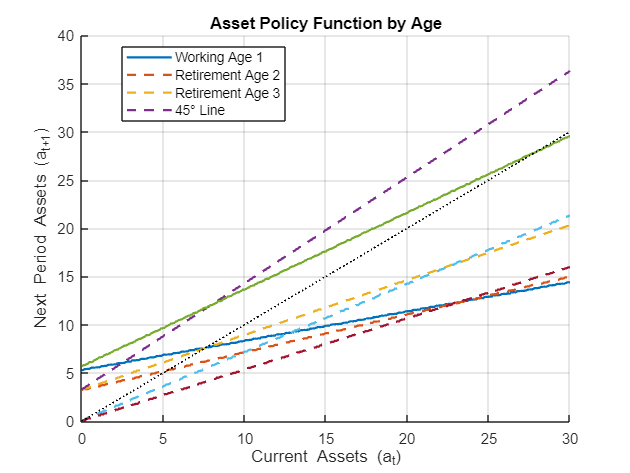

my_graph.plot_policy(par, sol);

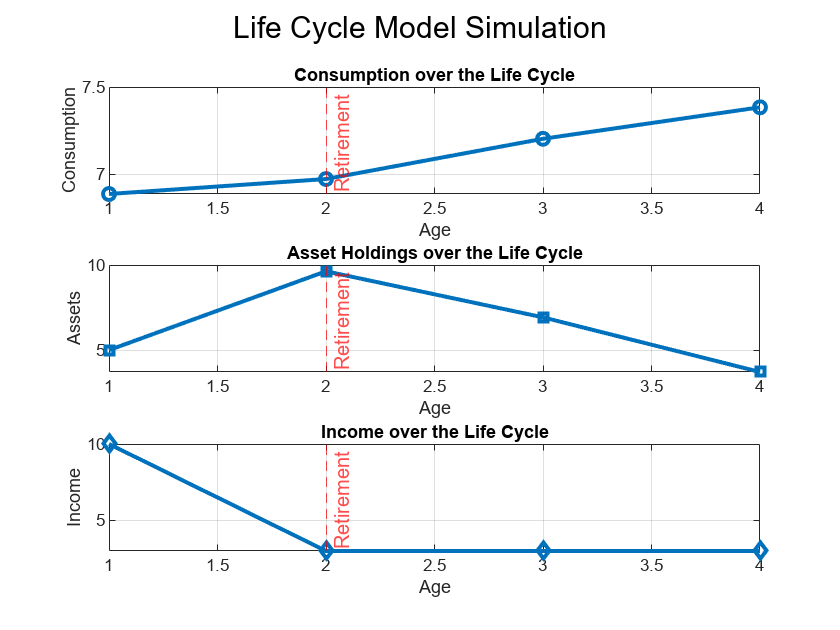

my_graph.plot_lifecycle(par, sim);

fprintf('\n============== Simulation Complete ==============\n')


============== Simulation Complete ==============


## (h) to (j)

%% Main script for Stochastic Life Cycle Model

% Clear workspace
clear;
clc;
close all;

fprintf('============== Stochastic Life Cycle Model Simulation ==============\n\n')

============== Stochastic Life Cycle Model Simulation ==============



%% Set up model parameters
fprintf('Setting up model parameters...\n')

Setting up model parameters...


par = model2.setup();
par = model2.gen_grids(par);

Income grid created with 7 states
Income states: [0.17, 0.27, ..., 2.68]



fprintf('Model Setup Complete:\n')

Model Setup Complete:


fprintf('- Lifespan (T): %d periods\n', par.T)

- Lifespan (T): 4 periods


fprintf('- Retirement begins at age: %d\n', par.tr)

- Retirement begins at age: 2


fprintf('- Initial wealth (a0): %.2f\n', par.a0)

- Initial wealth (a0): 5.00


fprintf('- Base income level: %.2f\n', par.ybar)

- Base income level: 1.00


fprintf('- Income persistence (rho): %.2f\n', par.rho)

- Income persistence (rho): 0.90


fprintf('- Income shock volatility (sigma_e): %.2f\n', par.sigma_e)

- Income shock volatility (sigma_e): 0.20


fprintf('- Pension rate (kappa): %.2f\n', par.kappa)

- Pension rate (kappa): 0.30


fprintf('- Discount factor (beta): %.2f\n', par.beta)

- Discount factor (beta): 0.96


fprintf('- Risk aversion (sigma): %.2f\n', par.sigma)

- Risk aversion (sigma): 2.00


fprintf('- Interest rate (r): %.2f\n\n', par.r)

- Interest rate (r): 0.10




%% Solve model (backward iteration)
fprintf('Solving the stochastic model using backward iteration...\n\n')

Solving the stochastic model using backward iteration...



sol = solve2.grow(par);

------------ Solving Stochastic Life Cycle Model Backward ------------

Solving for period 3...
Solving for period 2...
Solving for period 1...
------------ Solution Completed ------------



%% Simulate lifecycle
fprintf('\nSimulating life cycle...\n')


Simulating life cycle...


sim = simulate2.grow(par, sol);

%% Display results in table format
fprintf('\nLife Cycle Results (First 10 periods):\n')


Life Cycle Results (First 10 periods):


periods_to_show = min(10, par.T);
results_table = table((1:periods_to_show)', sim.a(1:periods_to_show), ...
                      sim.c(1:periods_to_show), sim.y(1:periods_to_show), ...
                      sim.s(1:periods_to_show), ...
                      'VariableNames', {'Age', 'Assets', 'Consumption', 'Income', 'IncomeState'});
disp(results_table)

    Age    Assets    Consumption    Income     IncomeState
    ___    ______    ___________    _______    ___________

     1          5      1.6915       0.17107         1     
     2     3.9967      1.7437       0.05132         1     
     3      2.709       1.732       0.05132         1     
     4     1.3043      1.7648       0.05132         1     




%% Plot results
fprintf('\nPlotting results...\n')


Plotting results...


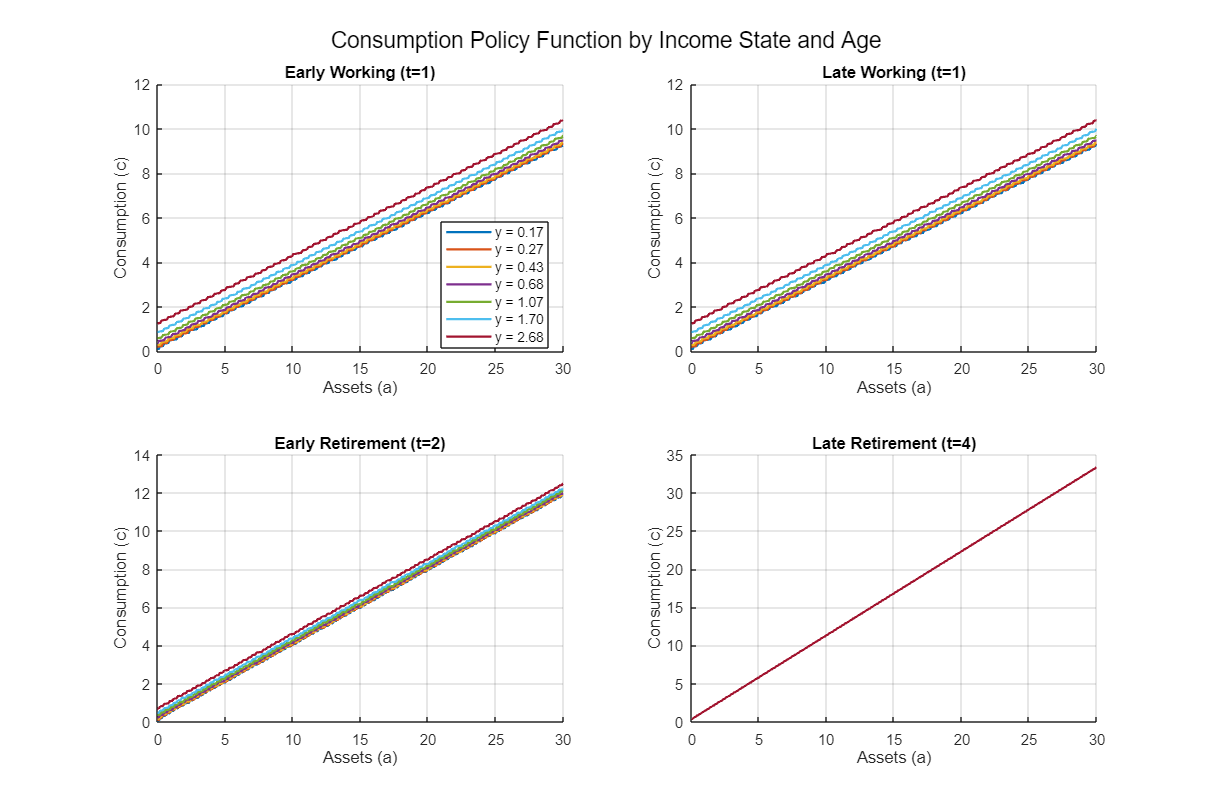

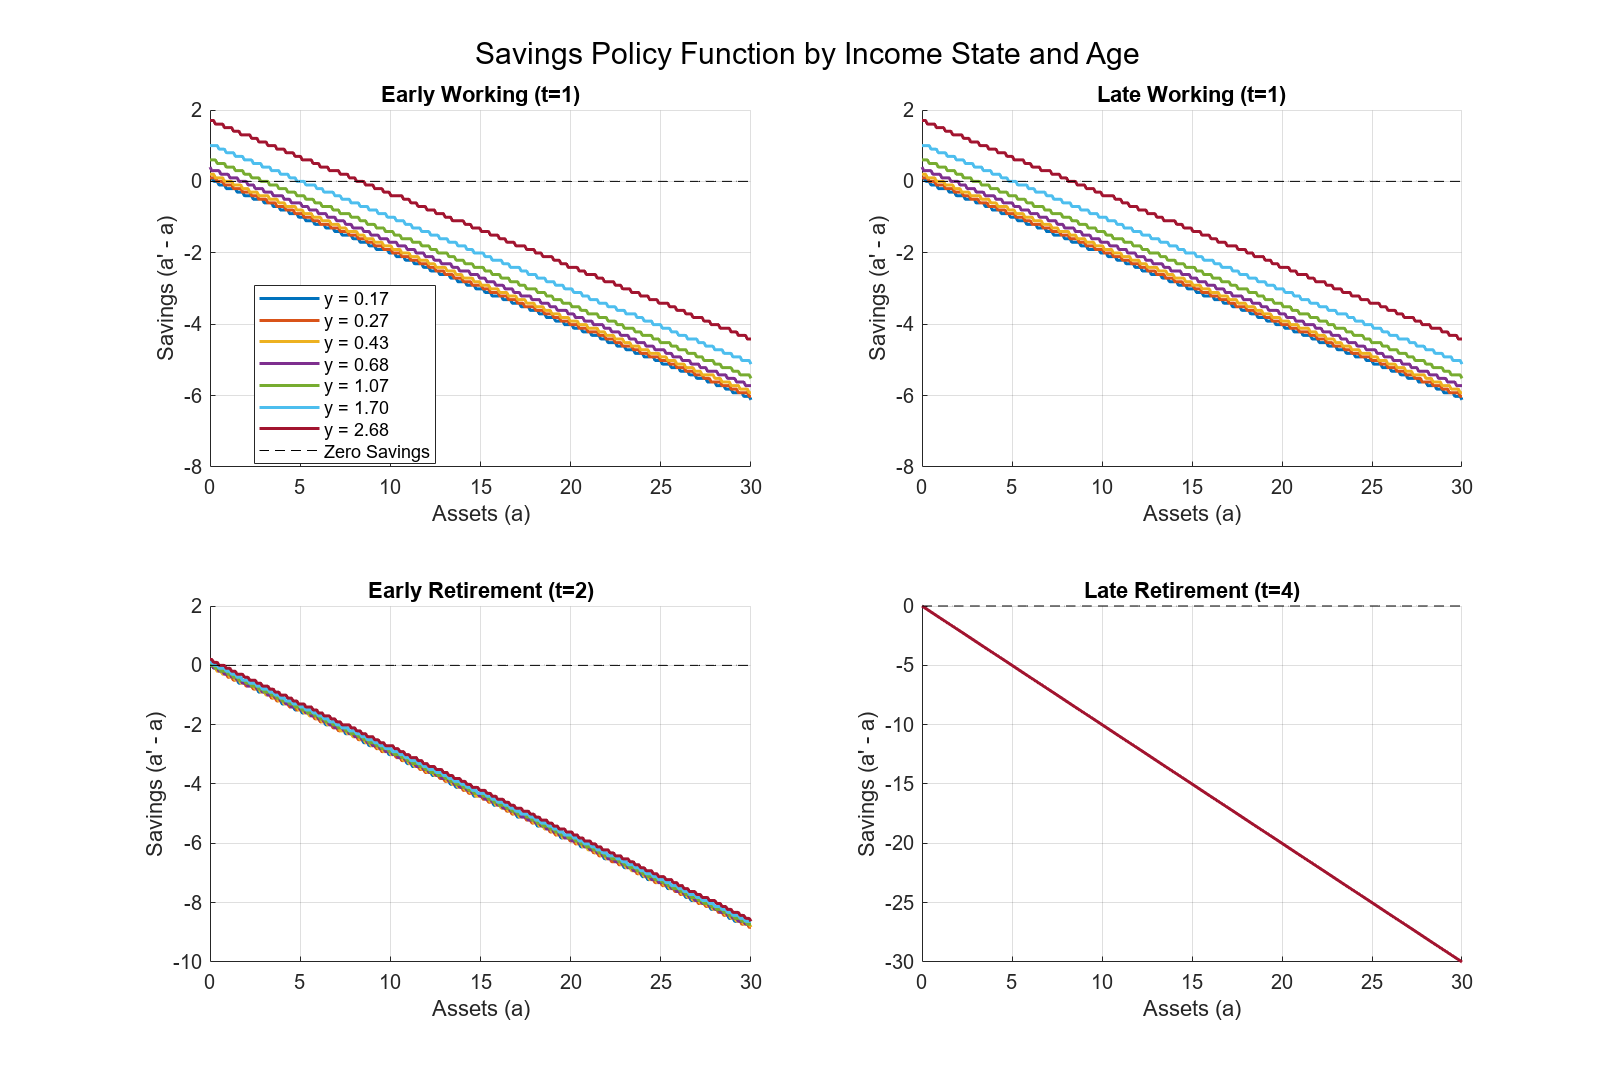

my_graph2.plot_policy(par, sol);

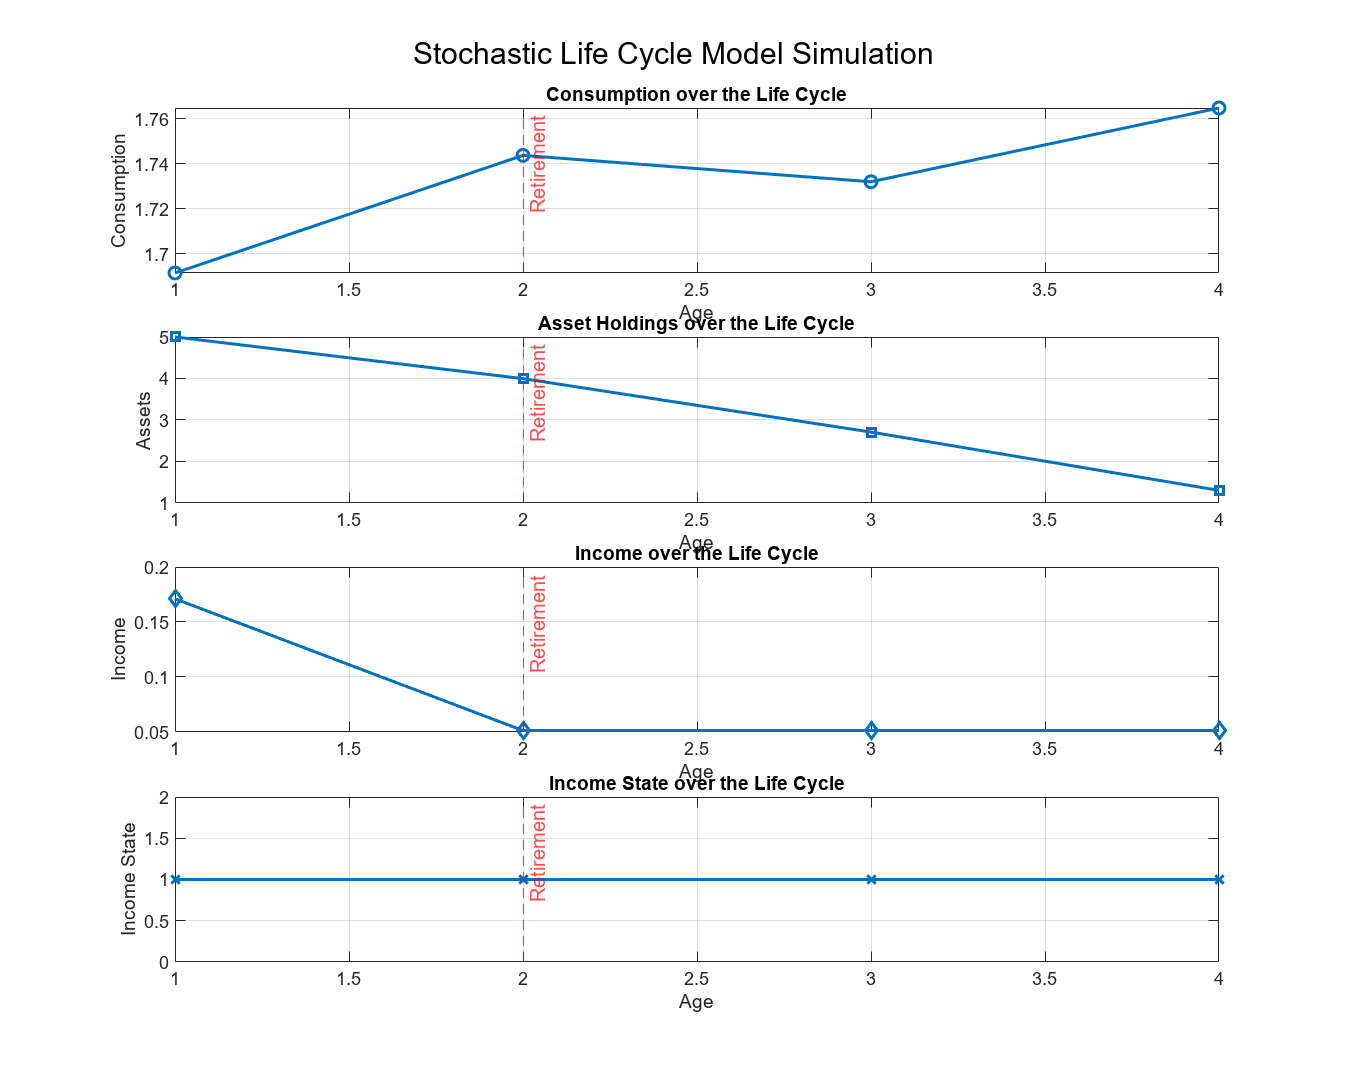

my_graph2.plot_lifecycle(par, sim);


%% Run multiple simulations to show range of outcomes
fprintf('\nRunning multiple simulations to show range of outcomes...\n')


Running multiple simulations to show range of outcomes...


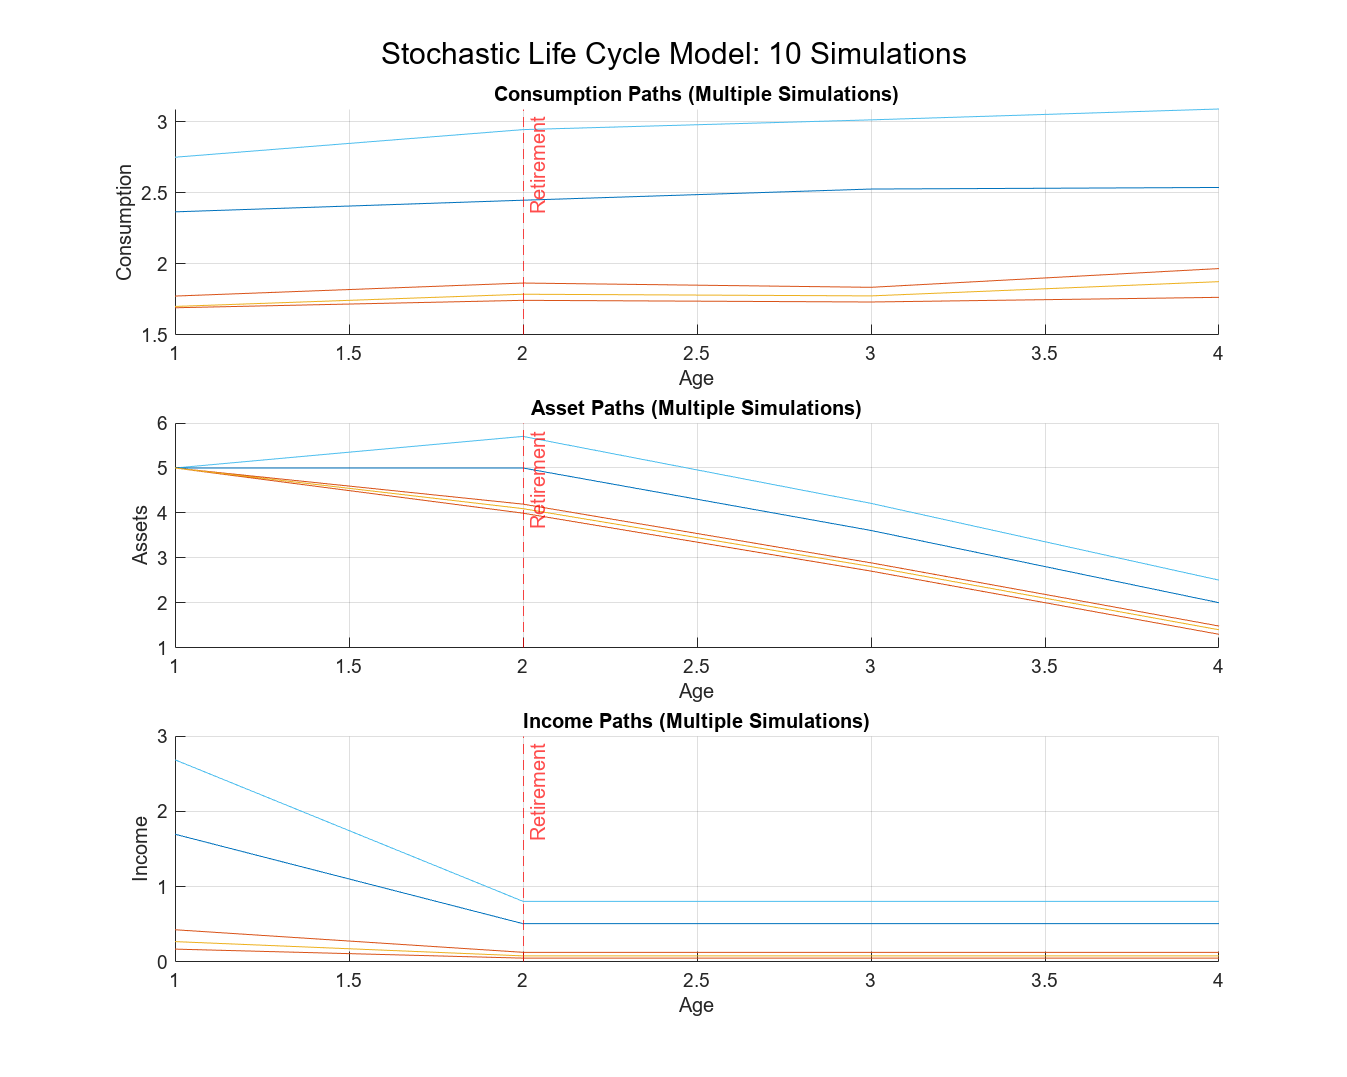

n_sims = 10;
all_sims = cell(n_sims, 1);

for i = 1:n_sims
    par.seed = par.seed + i;  % Change seed for each simulation
    all_sims{i} = simulate2.grow(par, sol);
end

my_graph2.plot_multi_lifecycle(par, all_sims, n_sims);


fprintf('\n============== Simulation Complete ==============\n')


============== Simulation Complete ==============



%% To run with longer lifecycle (T=60, tr=41), modify model.setup() parameters
fprintf('\nTo run with longer lifecycle (T=60, tr=41):\n')


To run with longer lifecycle (T=60, tr=41):


fprintf('1. Open model.m\n')

1. Open model.m


fprintf('2. Comment out lines for shorter life (T=4, tr=2)\n')

2. Comment out lines for shorter life (T=4, tr=2)


fprintf('3. Uncomment lines for longer life (T=60, tr=41)\n')

3. Uncomment lines for longer life (T=60, tr=41)


fprintf('4. Run this script again\n')

4. Run this script again
